# Liniowe systemy dynamiczne: defincja, wybrane własności, charakterystyki czasowe

Krzysztof Arent

2024

## laboratorium

#### imię i nazwisko studenta: Kacper Karkosz, Aleksander Łyskawa

### Zadanie 1

System dynamiczny może być postrzegany jako odwzorowanie przekształcające sygnały mające sens pobudzeń  (oddziaływujących na system) na przestrzeń sygnałów mających sens reakcji systemu na pobudzenia. Sygnały pobudzające są też nazywane wejściami systemu a stowarzyszone z nimi zmienne zmiennymi wolnymi. Z kolei sygnały mające sens reakcji na pobudzenia są też nazywane wyjściami systemu a stowarzyszone z nimi zmienne zmiennymi wynikowymi.

Przykładowo, silnik prądu stałego może być utożsamiany z odwzorowaniem przebiegu napięcia w czasie na stykach komutatora na przebieg prędkości kątowej w czasie na wale rotora.

Odwzorowanie pomiędzy przestrzeniami funkcyjnymi może być zdefiniowane przez równanie różniczkowe. Z tego powodu często dla rzeczywistych systemów dynamicznych poszukuje się równań różniczkowych, które przekształcają przestrzeń sygnałów wejściowych w przestrzeń sygnałów wyjściowych dokładnie tak samo jak procesy fizyczne (innymi słowy są wejściowo-wyjściowo równoważne).

Rozważmy równanie różniczkowe dwóch zmiennych


$$\ddot{y}(t)+a_1 \dot{y}(t) + a_0 y(t) = b_0 u(t) \quad (1)$$


Przyjąć $a_1=3, ~a_0=2, ~b_0=2.$  

#### 1) 

Wyznaczyć rozwiązanie analityczne (symboliczne) równania (1) dla przypadku gdy $y(0)=1, ~\dot{y}(0)=5$oraz $u(t)=sin(\frac{1}{3}t)$ dla $t \geq 0$. Przedstawić na jednym wykresie przebieg czasowy $u(t)$ oraz przebieg czasowy rozwiązania $y(t)$ dla $t \in [0,50]$.

Powyższe zadanie można zrealizować w sposób następujący:

clear all
close all
syms t y(t) u(t)  % deklaracja zmiennych i funkcji symbolicznych (obiektów klasy sym)
% definicja zmiennej u w równaniu różniczkowym (1)
u(t)=sin(1/3*t);
% definicje parametrów równania różniczkowego (1)
a1=3;
a0=2;
b0=2;
% implementacja równania różniczkowego (1)
rownanie=diff(y(t),t,2)+a1*diff(y(t),t,1)+a0*y(t)== b0*u(t)

$$rownanie = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+3\,\frac{\partial }{\partial t}y\left(t\right)+2\,y\left(t\right)=2\,\sin\left(\frac{t}{3}\right)$$

% specyfikacja warunków początkowych równania różniczkowego (1)
Dy(t)=diff(y(t),t,1)    % definicja funkcji symbolicznej - pochodnej funkcji y(t)

$$Dy(t) = \frac{\partial }{\partial t}y\left(t\right)$$

war_pocz=[y(0)==1, Dy(0)==5]

$$war\_pocz = \left(\begin{array}{cc} y\left(0\right)=1 & \left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)=5 \end{array}\right)$$

% wyznaczanie rozwiązania analitycznego równanania różniczkowego (1) dla ustalonych
% warunków początkowych
rozwiazanie = dsolve(rownanie,war_pocz)

$$rozwiazanie = \frac{38\,{\mathrm{e}}^{-t}}{5}-\frac{228\,{\mathrm{e}}^{-2\,t}}{37}-\frac{9\,\sqrt{370}\,\cos\left(\frac{t}{3}+\mathrm{atan}\left(\frac{17}{9}\right)\right)}{185}$$

y_rozw(t)=simplify(rozwiazanie)

$$y\_rozw(t) = \frac{38\,{\mathrm{e}}^{-t}}{5}-\frac{228\,{\mathrm{e}}^{-2\,t}}{37}-\frac{9\,\sqrt{370}\,\cos\left(\frac{t}{3}+\mathrm{atan}\left(\frac{17}{9}\right)\right)}{185}$$

% przedział czasu
T=[0,50]

T =      0    50


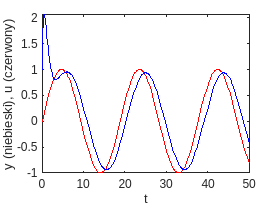

% wykreślanie przebiegów czasowych u(t) i y(t) na przedziale czasu T
figure(1);
fplot(u(t),T,'red')
hold on
fplot(y_rozw(t),T,'blue')
hold off
ylabel('y (niebieski), u (czerwony)'), xlabel('t')

Czy zmienną $u$ w równaniu (1) można uznać za pobudzenie a zmienną $y$ za reakcję na pobudzenie? Krótko uzasadnij swoją odpowiedź.

**Odpowiedź.** TAK, ponieważ w równaniu występują pochodne zmiennej y, które wskazują na dynamiczną odpowiedź na zmienną u(t), która jest wejściem.

#### 2)

Wyznaczyć rozwiązanie analityczne (symboliczne) równania (1) dla przypadku gdy $y(0)=0, ~\dot{y}(0)=0$ oraz $u(t)=sin(\frac{1}{3}t)$ dla $t \geq 0$. Przedstawić na wykresie przebiegi czasowe $u(t)$ oraz rozwiązania $y(t)$ dla $t \in [0,50]$.

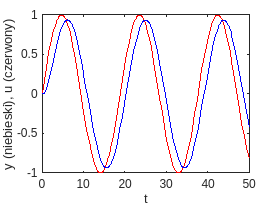

% Wpisz tutaj odpowiedni kod w Matlabie, którego wykonanie dostarczy rozwiązania
% powyżej postawionego zadania.
clear all
%close all
syms t y(t) u(t)  % deklaracja zmiennych i funkcji symbolicznych (obiektów klasy sym)
% definicja zmiennej u w równaniu różniczkowym (1)
u(t)=sin(1/3*t);
% definicje parametrów równania różniczkowego (1)
a1=3;
a0=2;
b0=2;
% implementacja równania różniczkowego (1)
rownanie=diff(y(t),t,2)+a1*diff(y(t),t,1)+a0*y(t)== b0*u(t);
% specyfikacja warunków początkowych równania różniczkowego (1)
Dy(t)=diff(y(t),t,1);    % definicja funkcji symbolicznej - pochodnej funkcji y(t)
war_pocz=[y(0)==0, Dy(0)==0];
% wyznaczanie rozwiązania analitycznego równanania różniczkowego (1) dla ustalonych
% warunków początkowych
rozwiazanie = dsolve(rownanie,war_pocz);
y_rozw(t)=simplify(rozwiazanie);
% przedział czasu
T=[0,50];
% wykreślanie przebiegów czasowych u(t) i y(t) na przedziale czasu T
fplot(u(t),T,'red')
hold on
fplot(y_rozw(t),T,'blue')
hold off
ylabel('y (niebieski), u (czerwony)'), xlabel('t')

Porównaj przebiegi $y(t)$ uzyskane w tym i 1-wszym podpunkcie zadania. Jaki jest wpływ warunków początkowych na $y$ przy ustalonym $u$? Podaj krótkie wyjaśnienie.

**Odpowiedż:** Warunki początkowe równania różniczkowego przy ustalonym wejściu mają wpływ na początkowe około 6 sekund symulacji. Nie mają wpływu na właściwości systemu (te zależą od parametrów równania).

#### 3)

Wyznaczyć rozwiązanie analityczne (symboliczne) równania (1) dla przypadku gdy $y(0)=0, ~\dot{y}(0)=0$ oraz $u(t)=1$ dla $t \geq 0$. Przedstawić na wykresie przebiegi czasowe $u(t)$ oraz rozwiązania $y(t)$ dla $t \in [0,50]$.

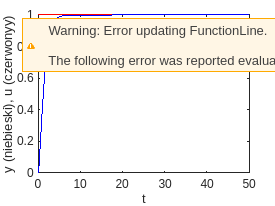

% Wpisz tutaj odpowiedni kod w Matlabie, którego wykonanie dostarczy rozwiązania
% powyżej postawionego zadania.
clear all
%close all
syms t y(t) u(t)  % deklaracja zmiennych i funkcji symbolicznych (obiektów klasy sym)
% definicja zmiennej u w równaniu różniczkowym (1)
u(t)=1;
% definicje parametrów równania różniczkowego (1)
a1=3;
a0=2;
b0=2;
% implementacja równania różniczkowego (1)
rownanie=diff(y(t),t,2)+a1*diff(y(t),t,1)+a0*y(t)== b0*u(t);
% specyfikacja warunków początkowych równania różniczkowego (1)
Dy(t)=diff(y(t),t,1);    % definicja funkcji symbolicznej - pochodnej funkcji y(t)
war_pocz=[y(0)==0, Dy(0)==0];
% wyznaczanie rozwiązania analitycznego równanania różniczkowego (1) dla ustalonych
% warunków początkowych
rozwiazanie = dsolve(rownanie,war_pocz);
y_rozw(t)=simplify(rozwiazanie);
% przedział czasu
T=[0,50];
% wykreślanie przebiegów czasowych u(t) i y(t) na przedziale czasu T
figure(3);
fplot(u(t),T,'red')
hold on
fplot(y_rozw(t),T,'blue')
hold off
ylabel('y (niebieski), u (czerwonyy)'), xlabel('t')

Porównaj przebiegi $y(t)$ uzyskane tym i 2-gim podpunkcie zadania. Czy dla znacząco różnych pobudzeń $u$ rozwiązania równania (1) są również znacząco różne? W konsekwencji, czy na gruncie dotychczasowych eksperymentów numerycznych możemy przypuszczać, że równanie różniczkowe (1) definiuje odwzorowanie z przestrzeni funkcji mających sens pobudzeń w inną przestrzeń funkcji mających sens reakcji na pobudzenia? Uzasadnij krótko swoją odpowiedź.

**Odpowiedż:** Tak, dla znacząco różnych pobudzeń $u$ rozwiązania równania (1) są znacząco różne. Zmiana pobudzenia prowadzi do przewidywalnych zmian w odpowiedzi systemu, dlatego możemy przypuszczać, że równanie różniczkowe (1) definiuje odwzorowanie z przestrzeni funkcji mających sens pobudzeń w inną przestrzeń funkcji mających sens reakcji na pobudzenia

### Zadanie 2

Mówimy, że system dynamiczny z wejściem $u$ i wyjściem $y$ jest liniowy wtedy i tylko wtedy gdy dla tego systemu jest spełniona zasada superpozycji. Konkretnie, jeżeli $u_1, ~u_2$ oznaczają dwa pobudzenia podane na wejście systemu a $y_1, ~y_2$ są reakcjami systemu na te pobudzenia to dla pobudzenia $u_3:=\alpha_1 u_1 + \alpha_2 u_2$ reakcja systemu przyjmie postać $y_3=\alpha_1 y_1 + \alpha_2 y_2$ dla dowolnych $\alpha_1, ~\alpha_2 \in \mathbb{R}$.

#### 1)

Rozważmy system dynamiczny reprezentowany przez równanie różniczkowe (1). Niech $a_1=3, ~a_0=2, ~b_0=2,$ $y(0)=0, ~\dot{y}(0)=0$, $u_1(t)=sin(t), ~u_2(t)=1$dla $t \geq 0$. Należy sprawdzić, że dla rozważanego systemu i przyjętych pobudzeń warunek zasady superpozycji jest spełniony.

Powyższe zadanie można zrealizować w sposób następujący

clear all
close all
syms t y(t) y1(t) y2(t) y3(t) u(t) u1(t) u2(t) u3(t) % deklaracja zmiennych i funkcji symbolicznych
% definicja zmiennych u1, u2
u1(t)=sin(t);
u2(t)=1;

% definicje parametrów równania różniczkowego (1)
a1=3;
a0=2;
b0=2;

% implementacja równania różniczkowego (1) dla u=u1 i u=u2
u(t)=u1(t);
rownanie1=diff(y(t),t,2)+a1*diff(y(t),t,1)+a0*y(t)== b0*u(t)

$$rownanie1 = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+3\,\frac{\partial }{\partial t}y\left(t\right)+2\,y\left(t\right)=2\,\sin\left(t\right)$$

u(t)=u2(t);
rownanie2=diff(y(t),t,2)+a1*diff(y(t),t,1)+a0*y(t)== b0*u(t)

$$rownanie2 = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+3\,\frac{\partial }{\partial t}y\left(t\right)+2\,y\left(t\right)=2$$

% specyfikacja warunków początkowych równania różniczkowego (1)
Dy(t)=diff(y(t),t,1)    % definicja funkcji symbolicznej - pochodnej funkcji y(t)

$$Dy(t) = \frac{\partial }{\partial t}y\left(t\right)$$

war_pocz=[y(0)==10, Dy(0)==15]

$$war\_pocz = \left(\begin{array}{cc} y\left(0\right)=10 & \left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)=15 \end{array}\right)$$

% wyznaczanie rozwiązania analitycznego równanania różniczkowego (1) dla ustalonych
% warunków początkowych
rozwiazanie1 = dsolve(rownanie1,war_pocz);
rozwiazanie2 = dsolve(rownanie2,war_pocz);
y1(t)=rozwiazanie1

$$y1(t) = 36\,{\mathrm{e}}^{-t}-\frac{127\,{\mathrm{e}}^{-2\,t}}{5}-\frac{\sqrt{10}\,\cos\left(t+\mathrm{atan}\left(\frac{1}{3}\right)\right)}{5}$$

y2(t)=rozwiazanie2

$$y2(t) = 33\,{\mathrm{e}}^{-t}-24\,{\mathrm{e}}^{-2\,t}+1$$

% warunek zasady superpozycji
alfa=rand(2,1)*10;
u3(t)=alfa(1)*u1(t)+ alfa(2)*u2(t)

$$u3(t) = \frac{7375747816469361\,\sin\left(t\right)}{1125899906842624}+\frac{57213917970985}{35184372088832}$$

y3(t)=alfa(1)*y1(t)+ alfa(2)*y2(t)

$$y3(t) = \frac{81486204692564289\,{\mathrm{e}}^{-t}}{281474976710656}-\frac{1156421417700191247\,{\mathrm{e}}^{-2\,t}}{5629499534213120}-\frac{7375747816469361\,\sqrt{10}\,\cos\left(t+\mathrm{atan}\left(\frac{1}{3}\right)\right)}{5629499534213120}+\frac{57213917970985}{35184372088832}$$

% sprawdzenie warunku zasady superpozycji
if simplify(diff(y3(t),t,2)+a1*diff(y3(t),t,1)+a0*y3(t)== b0*u3(t))
    disp(':)')
else
    disp(':(')
end

:)


Czy kilkukrotne wykonanie powyższego skryptu zwraca inny wynik niż **:)** ? Czy zmiana wartości warunków początkowych z zerowych na inne ma wpływ na uzyskany wynik?

**Odpowiedź**: Kilkukrotne wykonanie powyższego skryptu nie zwraca innego wyniku niż "**:)**". Zmiana wartości warunków początkowych z zerowych na inne nie ma wpływu na uzyskany wynik - program zawsze zwraca ":)". 

**2)**

Zbadać liniowość systemu


$$\ddot{y}(t)+a_1 \dot{y}(t) + a_0 y(t) = b_0 u(t) + 1 \quad (2)$$


w sposób identyczny jak w podpunkcie 1) tego zadania. Podobnie jak w podpunkcie 1-wszym przyjąć $a_1=3, ~a_0=2, ~b_0=2,$ $y(0)=0, ~\dot{y}(0)=0$, $u_1(t)=sin(t), ~u_2(t)=1$dla $t \geq 0$.

% Wpisz tutaj odpowiedni kod w Matlabie, którego wykonanie dostarczy rozwiązania
% powyżej postawionego zadania.
clear all
close all
syms t y(t) y1(t) y2(t) y3(t) u(t) u1(t) u2(t) u3(t) % deklaracja zmiennych i funkcji symbolicznych
% definicja zmiennych u1, u2
u1(t)=sin(t);
u2(t)=1;

% definicje parametrów równania różniczkowego (1)
a1=3;
a0=2;
b0=2;

% implementacja równania różniczkowego (1) dla u=u1 i u=u2
u(t)=u1(t);
rownanie1=diff(y(t),t,2)+a1*diff(y(t),t,1)+a0*y(t)== b0*u(t) + 1

$$rownanie1 = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+3\,\frac{\partial }{\partial t}y\left(t\right)+2\,y\left(t\right)=2\,\sin\left(t\right)+1$$

u(t)=u2(t);
rownanie2=diff(y(t),t,2)+a1*diff(y(t),t,1)+a0*y(t)== b0*u(t) + 1

$$rownanie2 = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+3\,\frac{\partial }{\partial t}y\left(t\right)+2\,y\left(t\right)=3$$

% specyfikacja warunków początkowych równania różniczkowego (1)
Dy(t)=diff(y(t),t,1)    % definicja funkcji symbolicznej - pochodnej funkcji y(t)

$$Dy(t) = \frac{\partial }{\partial t}y\left(t\right)$$

war_pocz=[y(0)==10, Dy(0)==15]

$$war\_pocz = \left(\begin{array}{cc} y\left(0\right)=10 & \left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)=15 \end{array}\right)$$

% wyznaczanie rozwiązania analitycznego równanania różniczkowego (1) dla ustalonych
% warunków początkowych
rozwiazanie1 = dsolve(rownanie1,war_pocz);
rozwiazanie2 = dsolve(rownanie2,war_pocz);
y1(t)=rozwiazanie1

$$y1(t) = 35\,{\mathrm{e}}^{-t}-\frac{249\,{\mathrm{e}}^{-2\,t}}{10}-\frac{\sqrt{10}\,\cos\left(t+\mathrm{atan}\left(\frac{1}{3}\right)\right)}{5}+\frac{1}{2}$$

y2(t)=rozwiazanie2

$$y2(t) = 32\,{\mathrm{e}}^{-t}-\frac{47\,{\mathrm{e}}^{-2\,t}}{2}+\frac{3}{2}$$

% warunek zasady superpozycji
alfa=rand(2,1)*10;
u3(t)=alfa(1)*u1(t)+ alfa(2)*u2(t);
y3(t)=alfa(1)*y1(t)+ alfa(2)*y2(t)

$$y3(t) = \frac{226447390207502943\,{\mathrm{e}}^{-t}}{1125899906842624}-\frac{330442558992561599\,{\mathrm{e}}^{-2\,t}}{2251799813685248}-\frac{267958957162129\,\sqrt{10}\,\cos\left(t+\mathrm{atan}\left(\frac{1}{3}\right)\right)}{1125899906842624}+\frac{18173035976822867}{2251799813685248}$$

% sprawdzenie warunku zasady superpozycji
if simplify(diff(y3(t),t,2)+a1*diff(y3(t),t,1)+a0*y3(t)== b0*u3(t) + 1)
    disp(':)')
else
    disp(':(')
end

:(


### Zadanie 3

Rozważmy system dynamiczny reprezentowany przez równanie różniczkowe dwóch zmiennych


$$\dddot{y}+a_2\ddot{y}(t)+a_1 \dot{y}(t) + a_0 y(t) = b_0 u(t) \quad (3)$$


Przyjąć $b_0=a_0$  natomiast wartości współczynników $a_0, ~a_1, ~a_2$ należy wyliczyć z następujących równań wielomianowych:

- 
$$s^3+a_2 s^2+a_1 s+a_0 = (s+1) (s+0.9) (s+0.8)$$


- 
$$s^3+a_2 s^2+a_1 s+a_0 = (s+1) (s+0.9+0.1 i) (s+0.9-0.1i)$$


Dla obydwu przypadków wyznaczyć

- czas opóźnienia $T_D, \quad (T_D: ~y(T_D) = 0.5 ))$

- czas ustalania $T_S, \quad (T_S: ~y(t) \in [0.9, 1.1], ~t \geq T_S)$

- przeregulowanie $(y_{max} -1)$

clear all
close all
syms t y(t) u(t)  % deklaracja zmiennych i funkcji symbolicznych (obiektów klasy sym)
% definicja zmiennej u w równaniu różniczkowym (3)
u(t)=1;
% definicje parametrów równania różniczkowego (3)
s=sym('s');
wspolczynniki1=coeffs(expand((s+1)*(s+0.9)*(s+0.8)))

$$wspolczynniki1 = \left(\begin{array}{cccc} \frac{18}{25} & \frac{121}{50} & \frac{27}{10} & 1 \end{array}\right)$$


% przypadek 1

a0=wspolczynniki1(1);
a1=wspolczynniki1(2);
a2=wspolczynniki1(3);
b0=a0;
% implementacja równania różniczkowego (3)
rownanie=diff(y(t),t,3)+a2*diff(y(t),t,2)+a1*diff(y(t),t,1)+a0*y(t)== b0*u(t)

$$rownanie = \frac{\partial^{3}}{\partial t^{3}}y\left(t\right)+\frac{27\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)}{10}+\frac{121\,\frac{\partial }{\partial t}y\left(t\right)}{50}+\frac{18\,y\left(t\right)}{25}=\frac{18}{25}$$

% specyfikacja warunków początkowych równania różniczkowego (3)
 Dy(t)=diff(y(t),t,1)    % definicja funkcji symbolicznej - pochodnej funkcji y(t)

$$Dy(t) = \frac{\partial }{\partial t}y\left(t\right)$$

DDy(t)=diff(y(t),t,2)    % definicja funkcji symbolicznej - drugiej pochodnej funkcji y(t)

$$DDy(t) = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)$$

war_pocz=[y(0)==0, Dy(0)==0, DDy(0)==0]

$$war\_pocz = \left(\begin{array}{ccc} y\left(0\right)=0 & \left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)=0 & \left({\left(\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)\right)|}_{t=0}\right)=0 \end{array}\right)$$

% wyznaczanie rozwiązania analitycznego równanania różniczkowego (3) dla ustalonych
% warunków początkowych
rozwiazanie = dsolve(rownanie,war_pocz)

$$rozwiazanie = 80\,{\mathrm{e}}^{-\frac{9\,t}{10}}-45\,{\mathrm{e}}^{-\frac{4\,t}{5}}-36\,{\mathrm{e}}^{-t}+1$$

y_rozw(t)=simplify(rozwiazanie);
% przedział czasu
T=[0,50]

T =      0    50


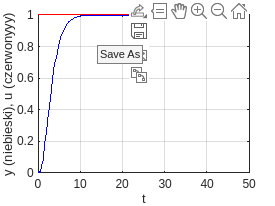

% wykreślanie przebiegów czasowych u(t) i y(t) na przedziale czasu T
figure(3)
fplot(u(t),T,'red')
hold on
fplot(y_rozw(t),T,'blue')
hold off
ylabel('y (niebieski), u (czerwonyyy)'), xlabel('t')
grid on


% przypadek 2

wspolczynniki2=coeffs(expand((s+1)*(s+0.2+0.3i)*(s+0.2-0.3i)))

$$wspolczynniki2 = \left(\begin{array}{cccc} \frac{13}{100} & \frac{53}{100} & \frac{7}{5} & 1 \end{array}\right)$$

% Wpisz tutaj odpowiedni kod w Matlabie, którego wykonanie dostarczy rozwiązania
% powyżej postawionego zadania.
a0=wspolczynniki2(1);
a1=wspolczynniki2(2);
a2=wspolczynniki2(3);
b0=a0;
% implementacja równania różniczkowego (3)
rownanie=diff(y(t),t,3)+a2*diff(y(t),t,2)+a1*diff(y(t),t,1)+a0*y(t)== b0*u(t)

$$rownanie = \frac{\partial^{3}}{\partial t^{3}}y\left(t\right)+\frac{7\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)}{5}+\frac{53\,\frac{\partial }{\partial t}y\left(t\right)}{100}+\frac{13\,y\left(t\right)}{100}=\frac{13}{100}$$

% specyfikacja warunków początkowych równania różniczkowego (3)
 Dy(t)=diff(y(t),t,1)    % definicja funkcji symbolicznej - pochodnej funkcji y(t)

$$Dy(t) = \frac{\partial }{\partial t}y\left(t\right)$$

DDy(t)=diff(y(t),t,2)    % definicja funkcji symbolicznej - drugiej pochodnej funkcji y(t)

$$DDy(t) = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)$$

war_pocz=[y(0)==0, Dy(0)==0, DDy(0)==0]

$$war\_pocz = \left(\begin{array}{ccc} y\left(0\right)=0 & \left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)=0 & \left({\left(\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)\right)|}_{t=0}\right)=0 \end{array}\right)$$

% wyznaczanie rozwiązania analitycznego równanania różniczkowego (3) dla ustalonych
% warunków początkowych
rozwiazanie = dsolve(rownanie,war_pocz)

$$rozwiazanie = 1-\frac{60\,\cos\left(\frac{3\,t}{10}\right)\,{\mathrm{e}}^{-\frac{t}{5}}}{73}-\frac{250\,\sin\left(\frac{3\,t}{10}\right)\,{\mathrm{e}}^{-\frac{t}{5}}}{219}-\frac{13\,{\mathrm{e}}^{-t}}{73}$$

y_rozw(t)=simplify(rozwiazanie);
% przedział czasu
T=[0,50]

T =      0    50


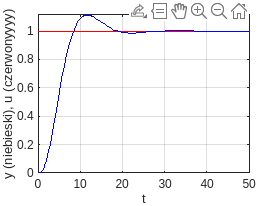

% wykreślanie przebiegów czasowych u(t) i y(t) na przedziale czasu T
figure(4)
fplot(u(t),T,'red')
hold on
fplot(y_rozw(t),T,'blue')
hold off
ylabel('y (niebieski), u (czerwonyyyy)'), xlabel('t')
grid on

**Odpowiedź**: 

przypadek nr 1

- czas opóźnienia: 3s

- czas ustalania: 5.95s

- przeregulowanie: 0

przypadek nr 2

- czas opóźnienia: 4.7156s % czas kiedy osiąga 0.5

- czas ustalania: 7.44s % czas kiedy trwale znajdzie sie w przedziale 0.9 - 1.1

- przeregulowanie: 0.1163

### Zadanie 4

Rozważmy system dynamiczny reprezentowany przez równanie różniczkowe dwóch zmiennych


$$\ddot{y}(t)+a_1 \dot{y}(t) + a_0 y(t) = b_0 u(t) \quad (3)$$


Przyjąć $b_0=a_0$  natomiast wartości współczynników $a_0, ~a_1,$ należy wyliczyć z następującego równania wielomianowego: $s^2+a_1 s+a_0 = (s+10) (s+10)$

Jesteśmy zainteresowani reakcją systemu (3) na pobudzenie piłokształtne $p(t)=R_m \frac{t ~\mathrm{ mod } ~T}{T}$ gdzie 27.27s $R_m$ jest amplitudą a $T$ okresem $p(t)$.  Sygnał $p(t)$można wyrazić w bazie funkcji harmonicznych w postaci nieskończonego szeregu Fouriera, $p(t)=\frac{R_m}{2} + \Sigma_{k=1}^{\infty} \frac{R_m}{k \pi} \cos (k \frac{2 \pi}{T}t + \frac{\pi}{2})$. Na wejście podamy aproksymację pobudzenia piłokształtnego składającą się ze składowej stałej i pierwszych 5-ciu harmonicznych z szeregu Fouriera.

Zbadać czy reakcja systemu (3), $y$, na takie pobudzenie ma przebieg w czasie zbliżony $u$ czy jest odkształcona dla $T=1, 2.5, 10, 25, 100$.

Powyższe zadanie można zrealizować przy użyciu poniższego kodu.

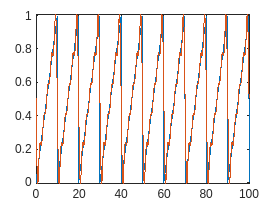

clear all
close all

% definicja sygnału piłokształtnego
T=10;
Rm=1;
p=@(t)(Rm * mod(t,T)/T);
% pierwsze sześć składowych szeregu Fouriera dla sygnału piłokształtnego
pf=@(t)(Rm/2+...
    Rm/(1*pi)*cos(1*(2*pi/T)*t + pi/2) + ...
    Rm/(2*pi)*cos(2*(2*pi/T)*t + pi/2) + ...
    Rm/(3*pi)*cos(3*(2*pi/T)*t + pi/2) + ...
    Rm/(4*pi)*cos(4*(2*pi/T)*t + pi/2) + ...
    Rm/(5*pi)*cos(5*(2*pi/T)*t + pi/2) );    
% porównanie sygnału piłokształtnego i jego przybliżenia złożonego z
% pierwszych sześciu składowych szeregu Fouriera

Tp=0:0.05:(T*10);

plot(Tp,p(Tp))
hold on
plot(Tp, pf(Tp))
hold off

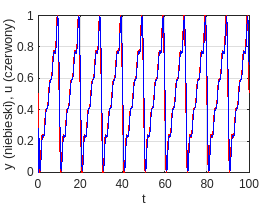


% definicja systemu dynamicznego
syms t y(t) u(t)  % deklaracja zmiennych i funkcji symbolicznych (obiektów klasy sym)
% definicja zmiennej u w równaniu różniczkowym (3)
u(t)=pf;
% definicje parametrów równania różniczkowego (3)
s=sym('s');
wspolczynniki=coeffs(expand((s+10)*(s+10)));

a0=wspolczynniki(1);
a1=wspolczynniki(2);
b0=a0;
% implementacja równania różniczkowego (2)
rownanie=diff(y(t),t,2)+a1*diff(y(t),t,1)+a0*y(t)== b0*u(t);
% specyfikacja warunków początkowych równania różniczkowego (2)
Dy(t)=diff(y(t),t,1);    % definicja funkcji symbolicznej - pochodnej funkcji y(t)
war_pocz=[y(0)==0, Dy(0)==0];
% wyznaczanie rozwiązania analitycznego równanania różniczkowego (1) dla ustalonych
% warunków początkowych
rozwiazanie = dsolve(rownanie,war_pocz);
y_rozw(t)=simplify(rozwiazanie);

% wykreślanie przebiegów czasowych u(t) i y(t) na przedziale czasu T
plot(Tp, real(double(u(Tp))),'red')
hold on
plot(Tp, real(double(y_rozw(Tp))),'blue')
hold off
ylabel('y (niebieski), u (czerwony)'), xlabel('t')
grid on

Wyjaśnić krótko dlaczego dla jednych wartości T (jakich?) sygnał wyjściowy $y$ znacząco różni się od $u$ a dla innych obydwa sygnały są do siebie bardzo zbliżone? Jaka powinna być zależność pomiędzy pulsacją najwyższej haromicznej sygnału wejściowego a pierwiastkiem wielomianu charakterystycznego równania różniczkowego (3)?

**Odpowiedź**: Dla T równych okresowi